# PRÁCTICA 4

# Herramientas matemáticas para el procesamiento de imágenes

## APLICACIÓN DE FUNCIONES DE TRANSFORMACIÓN (LUT)

<imagen salida> = intlut (<imagen entrada> , <vector LUT>);

NOTA: Tanto la imagen como el vector de transformación deben ser de tipo entero sin signo

### EJERCICIOS

1. Cargue la imagen ‘Gauges 00.tif’ (subdirectorio ‘Geometric Matching’), ‘Cables14.jpg’, ‘Pins-00.bmp’ y ‘Connector 01.jpg’ y muéstrelas en una figura (im1, im2, im3 e im4). (subplot)

im1 = imread("Gauges 00.tif");
im2 = imread("Cables14.jpg");
im3 = imread("Pins-00.bmp");
im4 = imread("Connector 01.jpg");
figure;
subplot(2,2,1);
imshow(im1);
subplot(2,2,2);
imshow(im2);
subplot(2,2,3);
imshow(im3);
subplot(2,2,4);
imshow(im4);

2. Cree unas LUT’s correspondientes a una rampa invertida y a escalones en 100 y 175. Visualícelas empleando en comando plot.

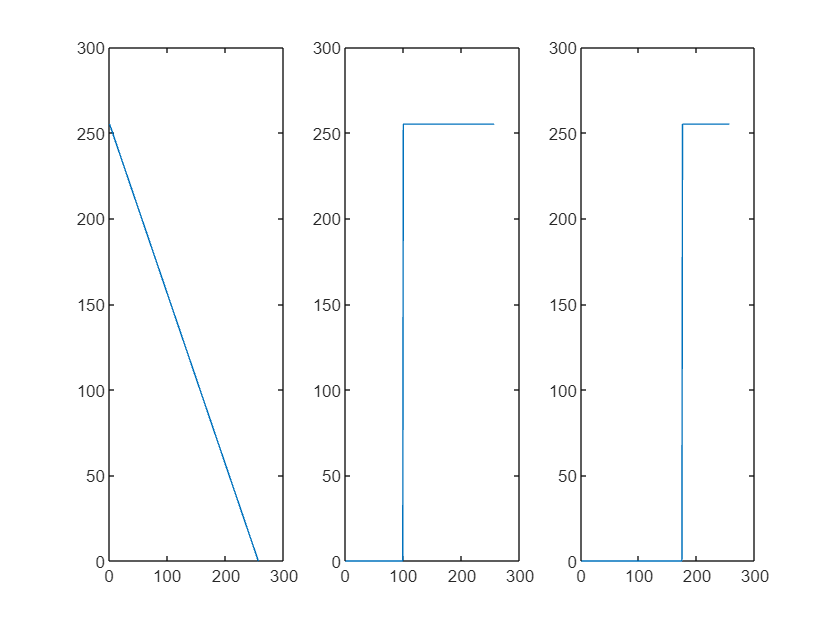

lutR = uint8([255:-1:0]); % crear rampa invertida.
lutE1 = uint8(zeros(256,1)); % crear escalón en el nivel 100
lutE1(100:end) = 255;
lutE2 = uint8(zeros(256,1)); % crear escalón en el nivel 175
lutE2(175:end) = 255;
figure;
subplot(1,3,1);
plot(lutR);
subplot(1,3,2);
plot(lutE1);
subplot(1,3,3);
plot(lutE2);

3. Muestre en una figura la imagen im1 y el resultado de aplicarle cada una de las LUT’s anteriores.

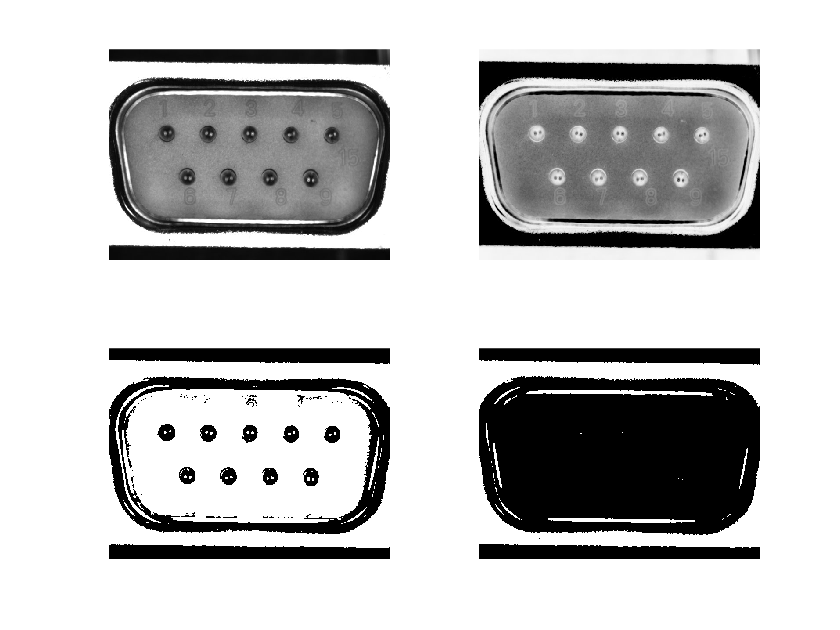

figure;
subplot(2,2,1);
imshow(im4);
subplot(2,2,2);
imshow(intlut(im4, lutR));
subplot(2,2,3);
imshow(lutE1(im4+1));
subplot(2,2,4);
imshow(intlut(im4, lutE2));

4. Repita el ejercicio 3 con las imágenes im3 e im4.

## CÁLCULO DE HISTOGRAMA

### EJERCICIOS

5. Visualice el histograma de la imagen im4 empleando directamente el comando imhist

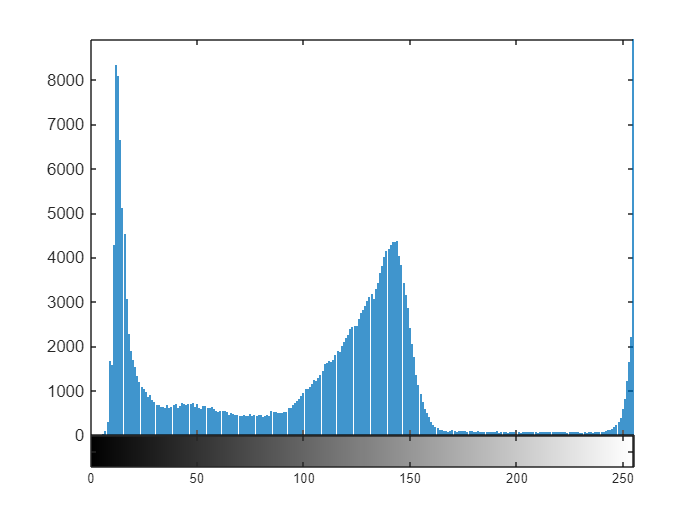

figure;
imhist(im4);

6. Asigne el histograma resultante a una variable y emplee el comando plot y el comando bar para visualizarlo.

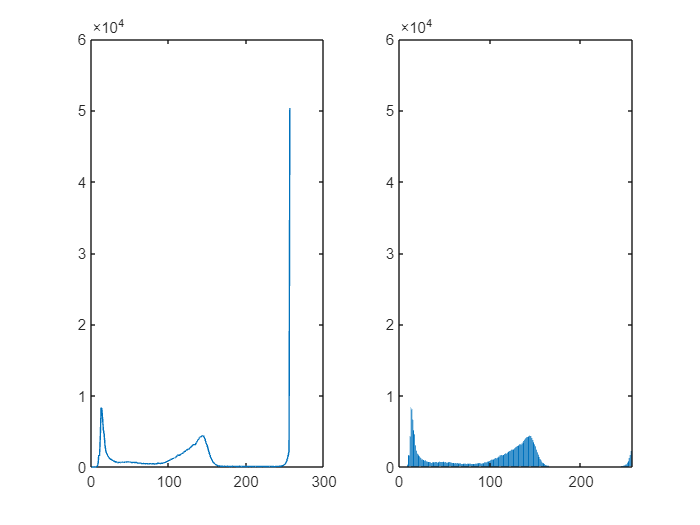

h4 = imhist(im4);
figure;
subplot(1,2,1);
plot(h4);
subplot(1,2,2);
bar(h4);

7. Muestre en una figura la imagen im3 su histograma normalizado. Compruebe que la suma de todos los valores de este histograma da como resultado 1.

figure;
h4n = h4/numel(im4);
sum(h4n)

ans = 1.0000

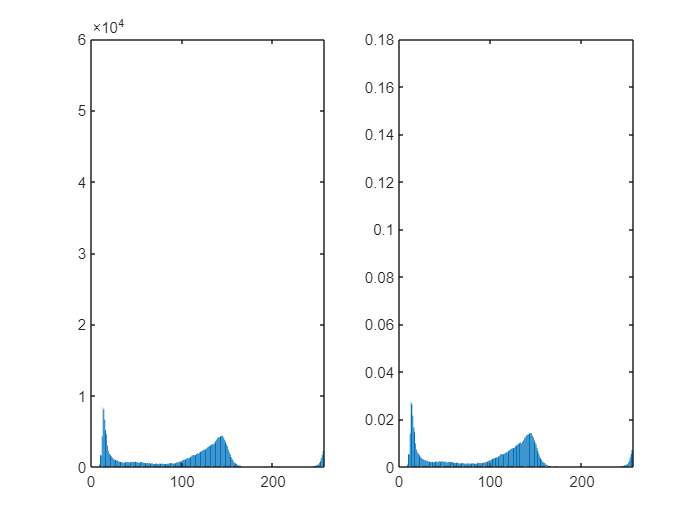

figure;
subplot(1,2,1);
bar(h4);
subplot(1,2,2);
bar(h4n);

8. Convierta la imagen im2 en HSV (im5) y muestre el histograma de la componente H empleando los comandos:

im5 = rgb2hsv(im2);
figure;
% pone a cero el matiz que tiene saturación pequeña
%imhist (((im5(:,:,1)).*(im5(:,:,2)>0.1))*255,hsv(256)); 
imhist ((im5(:,:,1))*255,hsv(256)); 

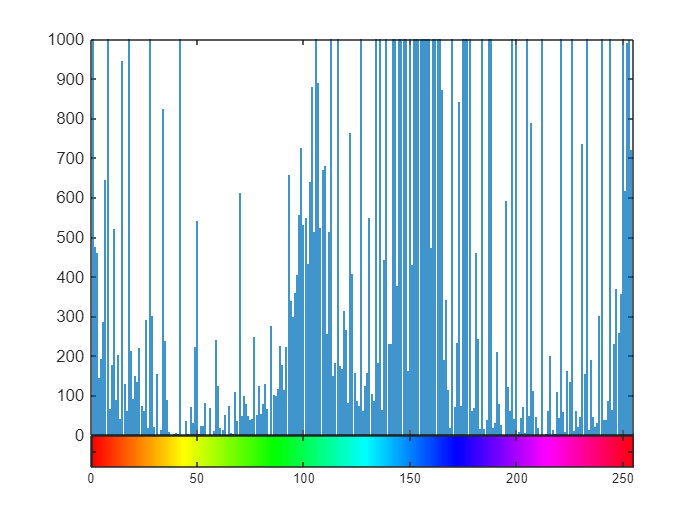

axis ([0 255 0 1000]);

NOTA: Este histograma permite conocer el ángulo normalizado correspondiente a los colores predominantes en la imagen (cable rojo, cable verde y cable azul)

## CONVOLUCION

### EJERCICIOS

9. Aplique promediado de entorno de vecindad 3x3, 9x9 y 20x20 a la imagen im4 empleando convolución (im6, im7 e im8) y muestre en una figura la imagen original y los resultados,

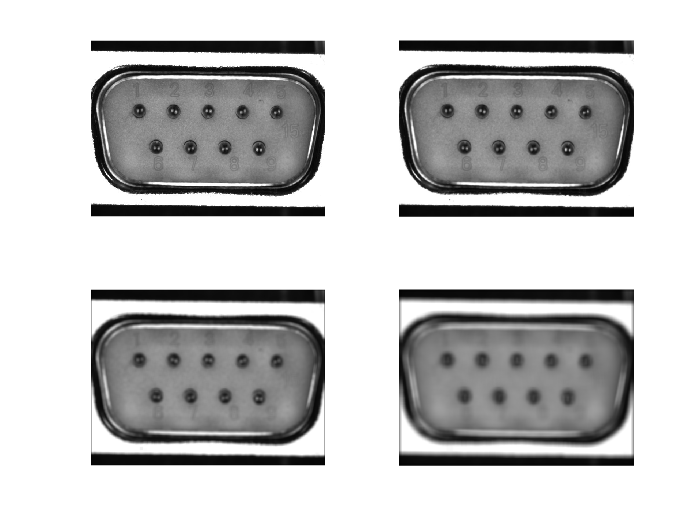

m3 = ones(3,3)/9; % define máscara para promediado 3x3
m9 = ones(9,9)/81; % define máscara para promediado 9x9
m17 = ones(17,17)/289; % define máscara para promediado 17x17
im6 = conv2(im4, m3, 'same');
im7 = conv2(im4, m9, 'same');
im8 = conv2(im4, m17, 'same');

figure;
subplot(2,2,1);
imshow(im4, []);
subplot(2,2,2);
imshow(im6, []);
subplot(2,2,3);
imshow(im7, []);
subplot(2,2,4);
imshow(im8, []);

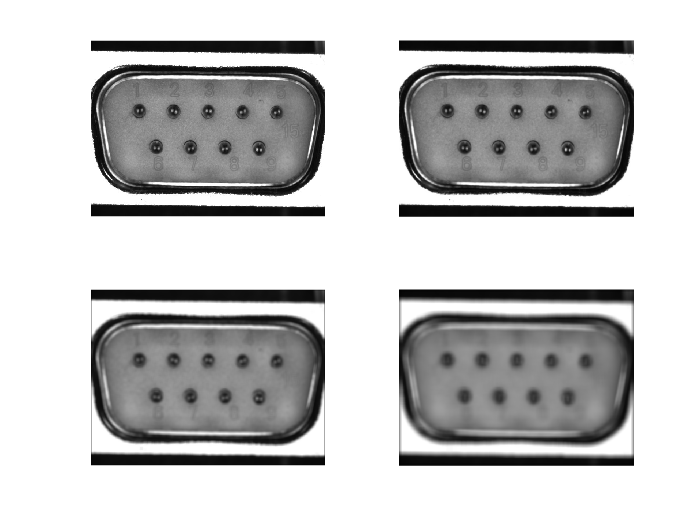

% IMFILTER NO SE DEBE USAR PARA DETECTAR DISCONTINUIDADES PORQUE SI HAY
% VALORES NEGATIVOS SE PIERDEN YA QUE DEVUELVE DEL MISMO TIPO
im6 = imfilter(im4, m3, 'conv');
im7 = imfilter(im4, m9, 'conv');
im8 = imfilter(im4, m17, 'conv');
figure;
subplot(2,2,1);
imshow(im4);
subplot(2,2,2);
imshow(im6, []);
subplot(2,2,3);
imshow(double(im7)/255);
subplot(2,2,4);
imshow(im8, []);

10. Visualice im8 como una superficie (interpole la superficie con shading interp).

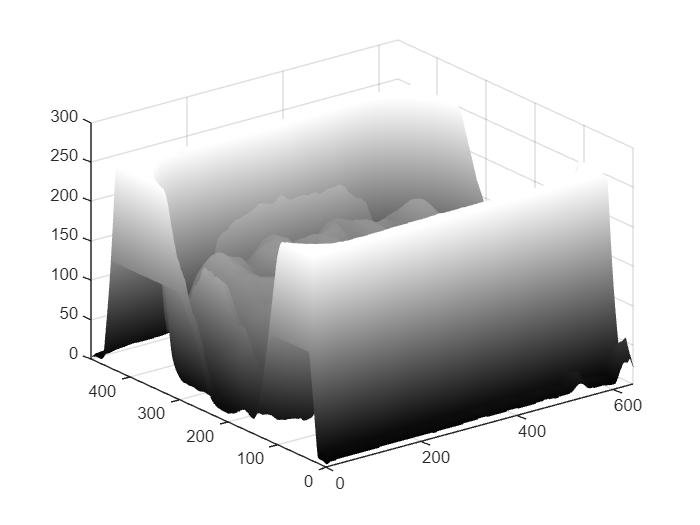

figure
surf(double(im8));
shading interp;
colormap gray;

## CORRELACIÓN CRUZADA NORMALIZADA

### EJERCICIO

11. Emplee la siguiente secuencia de comandos para localizar los pines en la imagen im4 por medio de correlación.

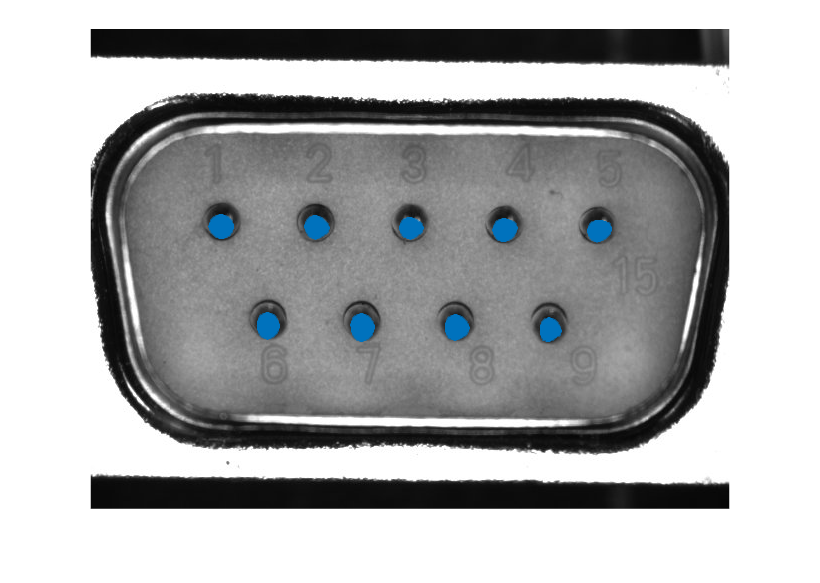

plantilla = im4(170:225 ,105:160); % crea plantilla con uno de los pines
imc = normxcorr2(plantilla,im4); % aplica correlación
[x,y] = find (imc>0.6); % localiza valores elevados
figure, imshow(im4); % muestra la imagen
hold on, plot(y-28, x-28,'*'); % superpone el resultado de la correlación a la imagen.

12. Visualice en dos figuras imc como imagen y como superficie (interpole la superficie con shading interp).

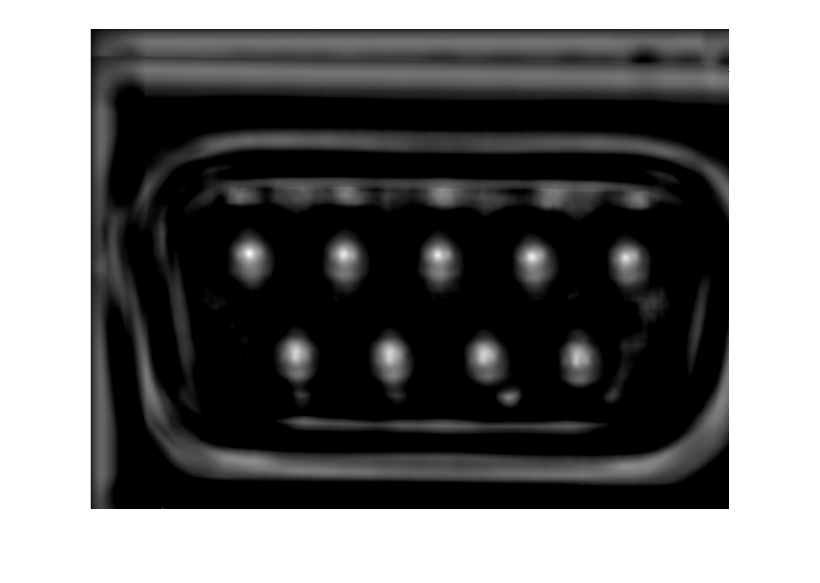

% LA IMAGEN ES M'AS GRANDE QUE LA ORIGINAL POR APLICAR LA MASCARA A LOS
% BORDES
imshow(imc);

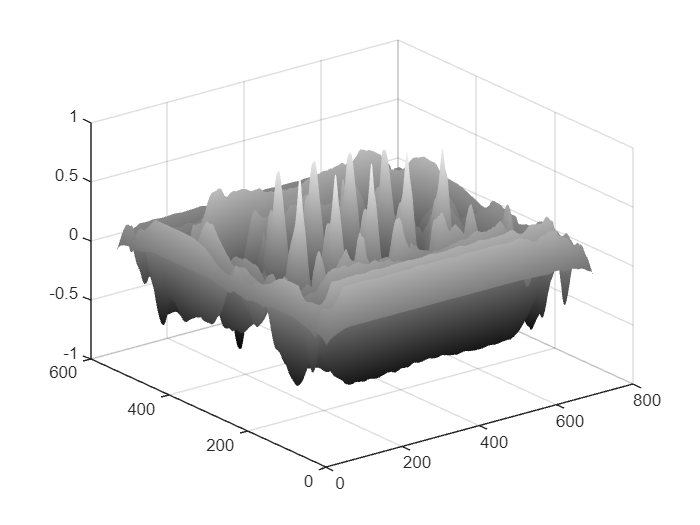

figure
surf(double(imc));
shading interp;
colormap gray;

13. Utilizando este código trate ahora de localizar los orificios en las piezas de la imagen im1, para ello será necesario que defina una nueva plantilla.

NOTA: puede emplear el comando imcrop para seleccionar parte de una imagen.

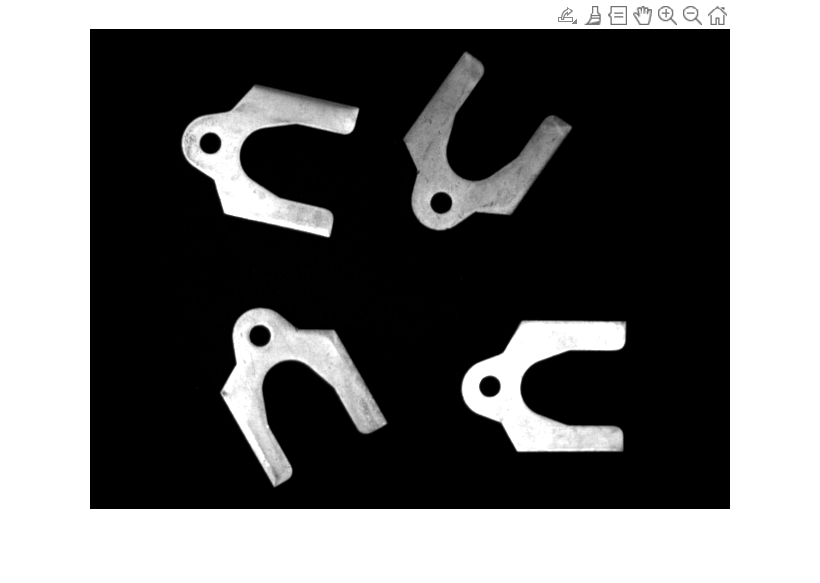

plantilla = imcrop(im1);

%figure;
%imshow(im1);
%[x,y] = ginput(2)

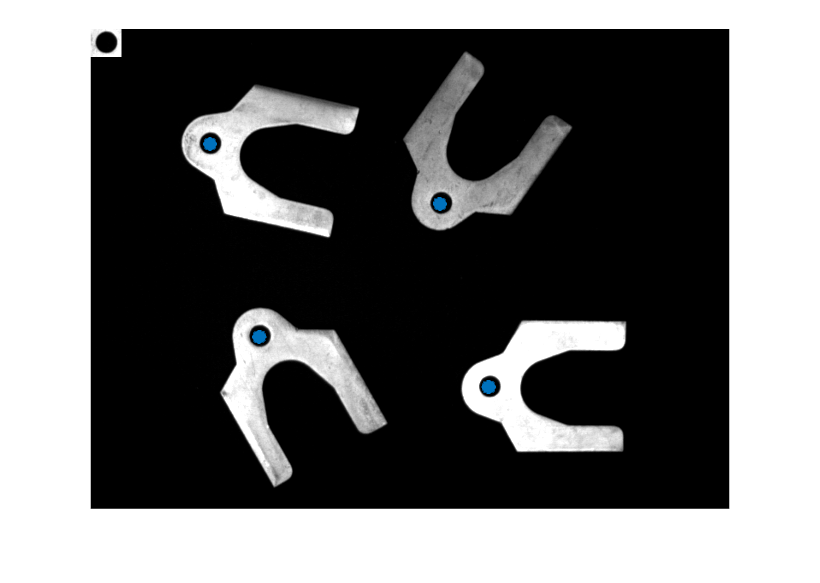

x = [108; 141];
y = [100; 133];
%sx = round(abs(x(2)-x(1)) /2);
%sy = round(abs(y(2)-y(1)) /2);
sx = size(plantilla,1)/2;
sy = size(plantilla,2)/2;
%plantilla = im1(round(x(1)):round(x(2)) ,round(y(1)):round(y(2))); % crea plantilla con uno de los pines
imc = normxcorr2(plantilla,im1); % aplica correlación
[x,y] = find (imc>0.8); % localiza valores elevados
figure, imshow(im1); % muestra la imagen
hold on, plot(y-sy, x-sx,'*'); % superpone el resultado de la correlación a la imagen.
imshow(plantilla);

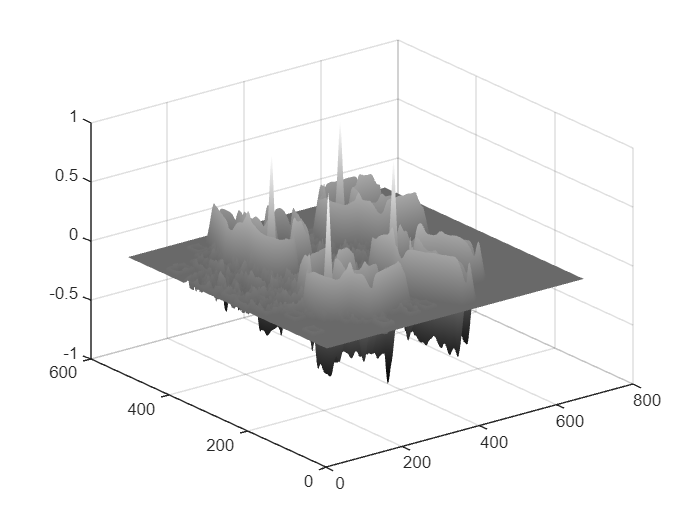

figure
%imshow(imc, [])
surf(double(imc));
shading interp;
colormap gray;

## TRANSFORMADA DE FOURIER (TdF)

### Cálculo de la transformada directa e inversa

### Visualizar el espectro de Fourier

### EJERCICIOS

14. Muestre el espectro de Fourier de la imagen im1 centrado y sin centrar en el plano imagen.

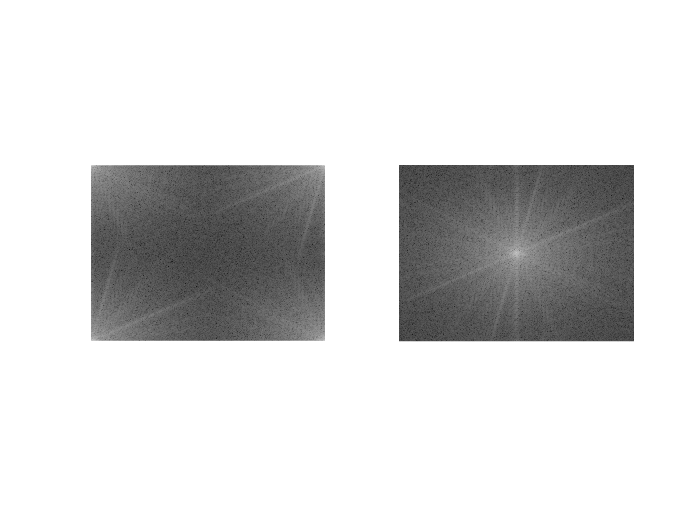

figure;
subplot(1,2,1);
imshow(30*log10(1+abs(fft2(im1)))/255);
subplot(1,2,2);
imshow(30*log10(1+abs(fftshift(fft2(im1))))/255);

15. Muestre en una figura la imagen im3 junto con su espectro centrado.

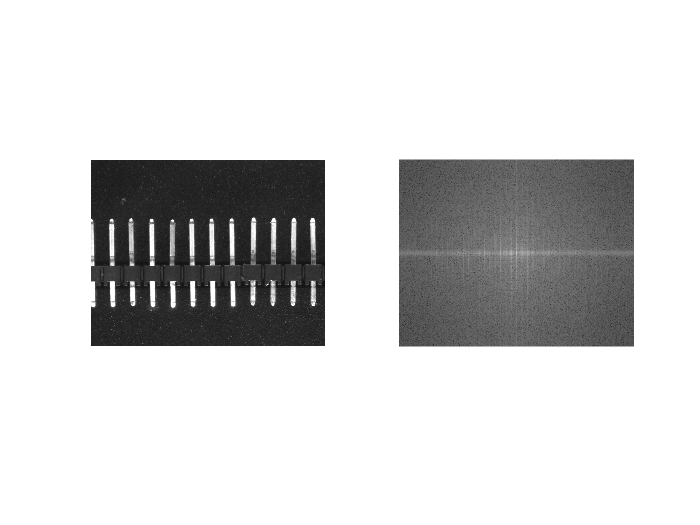

figure;
subplot(1,2,1);
imshow(im3);
subplot(1,2,2);
imshow(30*log10(1+abs(fftshift(fft2(im3))))/255);

16. Realice la convolución de la imagen im4 con la máscara m17 en el dominio de frecuencias (el resultado puede tener un residuo en forma de parte compleja que se debe eliminar con "real (resultado)"). 

im4t = fft2(im4);
[m, n] = size(im4);

m17t = fft2(m17, m, n);
rest = im4t .* m17t;
res = real(ifft2(rest));

Compruebe que coincide con la imagen suavizada en el ejercicio 9. ¿Existe alguna diferencia?

CONV (f(x, y), g(x, y)) <=> FFT (F(u,v)) .* FFT(G(u,v))

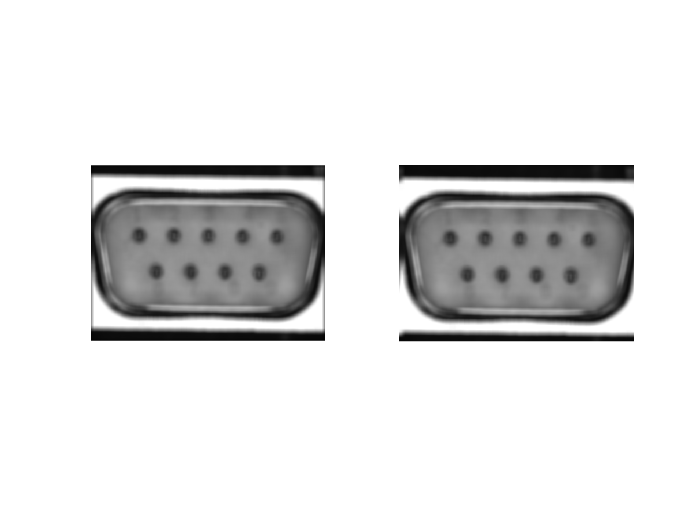

figure;
subplot(1,2,1);
imshow(im8);
subplot(1,2,2)
imshow(res/255);

17. Compruebe que la transformada de Fourier inversa se puede realizar aplicando la directa al conjugado de la transformada.

IFFT (F) <=> FFT (F*)

NOTA: recuerde que MATLAB realiza la división por el número de elementos únicamente en la transformación inversa, por lo que al no emplearla deberá dividir el resultado por numel (F)

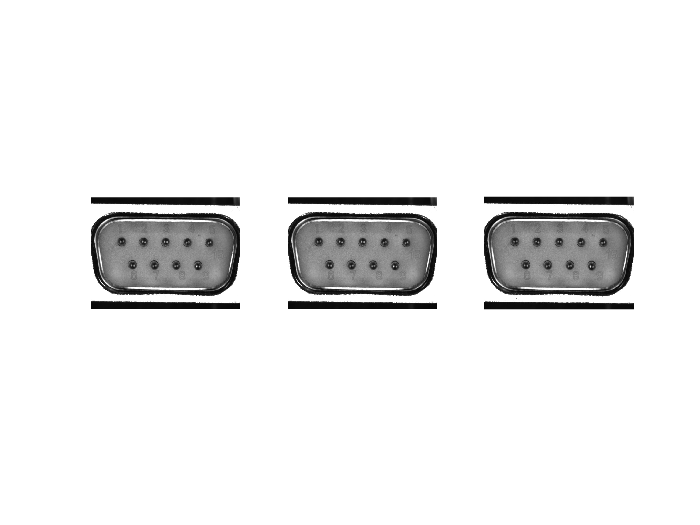

% OPCION 1: IMG == REAL(IFFT2(FFT2(IM))/255;
% OPCION 2: IMG == REAL(FFT2(CONJ(FFT2(IM))/numel(im))/255);

figure;
subplot(1,3,1);
imshow(im4);

subplot(1,3,2);
imshow(real(ifft2(fft2(im4)))/255);

subplot(1,3,3);
imshow(real(fft2(conj(fft2(im4)))/numel(im4))/255);